# Hands-on: the Sample Variance

## Introduction

In this section, we give a basic introduction to the sample variance for the readers who are less familiar with statistics. We emphasize those aspects that will be important to interpret the results from system identification. We also take the opportunity to introduce the concept  *bias-variance trade-off*. 

In the Hands-On [*Sample Mean and Median*](matlab:open('./L6_HandsON_SampleAverage.mlx')), the variability of the sample mean is characterized using the confidence interval that contains the true value of the mean with a user defined probability. The construction of this interval required the knowledge of the distribution of the random variable. In practice, a normal distribution is often assumed, but even then it is still necessary to know the variance of the r.v. . In this section we study how the variance can be estimated from the data using the sample variance. A new element will come into the picture compared to what we learned in the Hands-On *Sample Mean and Median:*

- The calculation of the sample variance requires the knowledge of the mean value $\mu$. First we will assume that we know the exact value $\mu$, next we replace the exact value $\mu$ by the sample mean $\hat \mu_N$ and analyze how this impacts the calculation and the properties of the sample variance.

What you will learn:

- Definition of the sample variance,

- Study of the properties of the sample variance, using respectively the exact mean $\mu$ and the sample mean $\hat \mu_N$,

- Study of the bias-variance trade-off that balances the systematic (bias) and the variability (variance) errors of an estimator.

## The Variance

The variance of a random variable $X$ with distribution $F(X)$ is 


$$E[(X-\mu)^2]=\int_{-\infty}^{\infty}(X-\mu)^2dF(X)=\int_{-\infty}^{\infty}(X-\mu)^2f(X)dX$$


where the latter equality holds if the pdf $f(X)$ exist. The variance is also known as the second central moment. 

## The Sample Variance

The sample variance of $N$ observations $\{x_i\}, i=1,\ldots,N$ of the random variable $X$ with known mean $\mu $ is defined as 


$$ \hat \sigma^2_{\mu,N}={\frac {1}{N}}\sum _{i=1}^{N}(x_{i}-\mu)^2.$$


We have added the subindex $\mu$ to indicate that we used the exact value of the mean to calculate the variance. In practice, the mean value is often unknown and replaced by the sample mean. In that case the sample variance is defined as


$$ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(x_{i}-\hat \mu_N)^2.$$


In this Hands-On, we will assume in the first part that the mean is known, in the second part the true value $\mu$ is replaced by the sample mean $\hat \mu_N$. The impact of this switch is studied, among others it will become clear why the scale factor $N$ is replaced by the factor $N-1$.This choice will be questioned in the Bias-Variance Trade-Off section.

## The Sample Variance $\hat \sigma^2_{\mu,N}$ (using the true mean) as an Estimator of the Variance of a Distribution

The sample variance is used to estimate the variance of a distribution. To judge if this is a good choice we study the stochastic properties of the sample variance $\hat \sigma^2_{\mu,N}$. 

*Remark*: in practice we often need the standard deviation $\sigma$ instead of the variance $\sigma^2$. The estimated value $\hat \sigma_N$ is obtained by taking the square root of the estimated variance: $\hat \sigma_{\mu,N}=\sqrt{\hat \sigma^2_{\mu,N}}$, so there is no need to develop a new estimator to estimate the standard deviation $\sigma$. 

### Study of the Stochastic Properties of the Sample Variance $\hat \sigma^2_{\mu,N}$

We will first study the mean $E[\hat \sigma^2_{\mu,N}]$, and verify these results on a simulation. Next, the spread of $\hat \sigma^2_{\mu,N}$ is characterized by constructing a dedicated confidence interval for the sample variance.

### Mean of the Sample Variance $E[\hat \sigma^2_{\mu,N}]$

The expected value $E[\hat \sigma^2_{\mu,N}]$ is directly calculated from its definition using the linearity of the expected value operator $E[a+b]=E[a]+E[b]$:


$$ E[\hat \sigma^2_{\mu,N}]={\frac {1}{N}}\sum _{i=1}^{N}E[(x_{i}-\mu)^2]={\frac {1}{N}}\sum _{i=1}^{N}\sigma^2=\sigma^2.$$


The second equality holds because by definition the variance of $x_i$ is $\sigma^2$.

In the example below, we illustrate the use of the estimator $ \hat \sigma^2_{\mu,N}={\frac {1}{N}}\sum _{i=1}^{N}(x_{i}-\mu)^2$ for the variance $\sigma^2$ for a growing number of uncorrelated samples (observations) $\{x_i\},i=1,\ldots,N$ drawn from a normal distribution $N(\mu=0,\sigma^2=1)$. In the figure we plot:

- $\hat \sigma^2_{\mu,N}$ for a growing number of samples $N$, using a logarithmic x-axis.

- On the left side, the results for a single realization of the simulation are shown. The points are connected by a line to give a better visual impression. 

- On the right plot, 100 realizations of the simulation are plotted on top of each other. These illustrate very well the stochastic nature of $\hat \sigma^2_{\mu,N}$, each realization results in a different line. However, some common characteristics can be observed.

- Observation 1: The initial variations of $\hat \sigma^2_{\mu,N}$ for small values of $N$ are large, but these drop to zero for growing values of $N$.

- Observation 2:  All the blue lines converge to the true value $\sigma^2=1$ for $N \rightarrow \infty$. The expected value $E[\hat \sigma^2_{\mu,N}]=1$. 

-  Observation 3: It will be shown below in  Distribution of the sample variance that the standard deviation  of $\hat \sigma^2_{\mu,N}$ is given by $\sigma_{\hat \sigma^2_{\mu,N}}=\sqrt{\frac{2}{N}}\sigma^2$. In the figure below, a symmetric confidence interval $[-1.96\sigma_{\hat \sigma^2_{\mu,N}},1.96\sigma_{\hat \sigma^2_{\mu,N}}]$ is plotted in red around the true value $\sigma^2=1$. If the sample variance was normally distributed, this confidence interval would contain the estimated value $\hat \sigma^2_{\mu,N}$ with a probability of 95%. This does not hold true in this example because the sample variance has a distribution that differs from the normal one. Especially for the lower values $N<10$ strong deviations can be seen. Observe also that the distribution of $\hat \sigma^2_{\mu,N}$ is not symmetric around the true value $\sigma=1$, it does not match well with a symmetric confidence interval. There are more outliers that are too large than too small. In the section Confidence interval, an asymmetric confidence interval for $\hat \sigma^2_{\mu,N}$ will be constructed, based on the true probability distribution of $\hat \sigma^2_{\mu,N}$.

- Push the Run Again button to get another realization of the simulation.

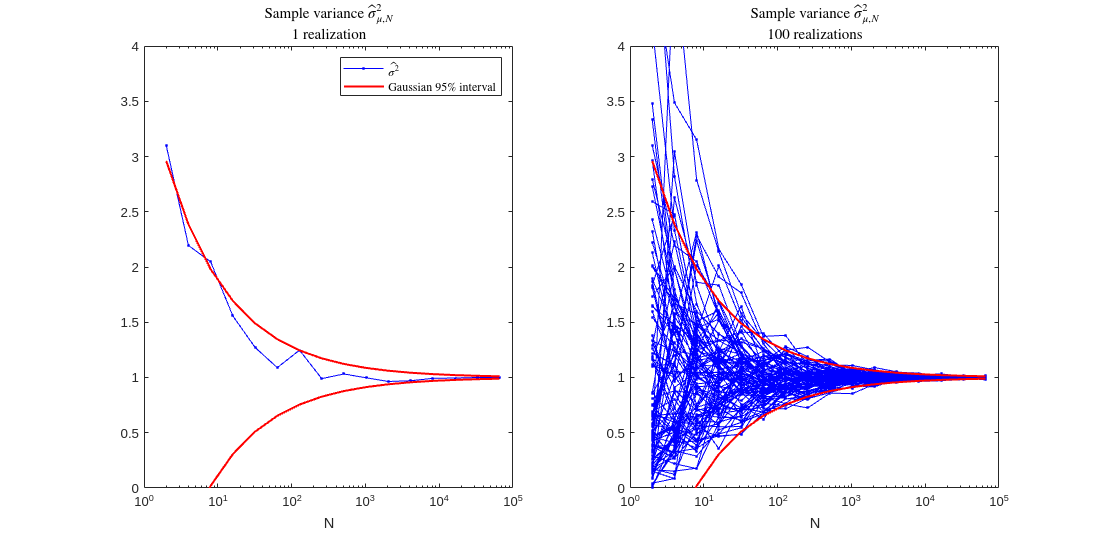

NAll=2.^(1:16);   % lengths of the data records
R=100;            % number of realizations
 
X=randn(max(NAll),R);      % generate the random data
XvarAll=zeros(length(NAll),R);  % initialize the matrix

for k=length(NAll):-1:1    % calculate the variance estimates
    XvarAll(k,:)=MyVarZeroMean(X(1:NAll(k),:),1);
end

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])
% plot the variances + Gaussian based confidence interval
subplot(1,2,1)
semilogx(NAll,XvarAll(:,1),'.-b')
hold on
semilogx(NAll,1+1.96*(2./NAll).^0.5,'r',NAll,1-1.96*(2./NAll).^0.5,'r','linewidth',1.5)
hold off
ylim([0,4])
xlabel('N')
title({'Sample variance $\hat \sigma^2_{\mu,N}$','1 realization'},'Interpreter','latex')
legend({'$\hat{\sigma^2}$','Gaussian 95\% interval'},'Interpreter','latex')

subplot(1,2,2)
semilogx(NAll,XvarAll(:,1:R),'.-b')
hold on
semilogx(NAll,1+1.96*(2./NAll).^0.5,'r',NAll,1-1.96*(2./NAll).^0.5,'r','linewidth',1.5)
hold off
ylim([0,4])
xlabel('N')
title({'Sample variance $\hat \sigma^2_{\mu,N}$','100 realizations'},'Interpreter','latex')

### Distribution of the Sample Variance $\hat \sigma^2_{\mu,N}$ (Hint: Not for One New to Statistics)

Consider $N$ independent observations $\{x_i\}, i=1,\ldots,N$of the normally distributed random variable $X$. The sample variance $\hat \sigma^2_{\mu,N}$ of these $N$ observations  is a random variable as well. To retrieve its distribution, we rewrite $\hat \sigma^2_{\mu,N}$ as:

  $ \hat \sigma^2_{\mu,N}={\frac {1}{N}}\sum _{i=1}^{N}(x_{i}-\mu)^2= \sigma^2{\frac {1}{N}}\sum _{i=1}^{N}(\frac{x_{i}-\mu}{\sigma})^2=\frac{\sigma^2}{N}Z$ with $Z=\sum _{i=1}^{N}z_i^2$.

The intermediate variables $z_i=\frac{x_{i}-\mu}{\sigma}\sim N(0,1)$ are independent standard ($\mu=0$ and $\sigma^2=1$) normally distributed, and hence $Z=\sum _{i=1}^{N}z_i^2$ has by definition a $\chi^2$-distribution with $\nu=N$ degrees of freedom. So $\frac{N}{\sigma^2}\hat \sigma^2_{\mu,N}\sim\chi^2(\nu=N)$. After rescaling, we find that $\hat \sigma^2_{\mu,N}\sim\frac{\sigma^2}{N}\chi^2(\nu=N)$. The $\chi^2(\nu)$-distribution has a mean value $\mu=\nu$ and a variance $\sigma^2=2\nu$. This implies immediately that  for $\nu=N$ the mean value $E[\hat \sigma^2_{\mu,N}]=\frac{\sigma^2}{N}N=\sigma^2$ (which is the value that we already retrieved before), and the variance of $\hat \sigma^2_{\mu,N}$ is $\sigma^2_{\hat \sigma^2_{\mu,N}}=(\frac{\sigma^2}{N})^22N=\frac{2\sigma^4}{N}$. 

Remark: the $\chi^2(\nu)$-distribution is characterized by a single parameter which is the degrees of freedom $\nu$. It is the number of independent and identically distributed normal random variables $z_i$ that show up in the sum $Z=\sum _{i=1}^{N}z_i^2$. The degrees of freedom is an important concept in the analysis of the flexibility of a model, and it will turn up again when we replace the exact mean value $\mu$ by the sample mean $\hat \mu_N$ in the calculation of the sample variance.

In the next figure, the pdf of the sample variance is shown for $\nu=N$degrees of freedom. The theoretical $\chi^2(\nu)$-distribution is compared to the estimated distribution (obtained from $10^4$ realizations). As a reference, also the normal distribution with the same mean and variance $N(1,\frac{2}{N})$ is plotted.

- Make the figure for $N=2,4,8,16,64$.

- The sample variance $\hat \sigma^2_{\mu,N}$ is lower bounded by zero, while it can stretch to large positive extreme values. This results in an asymetric pdf. 

- Compare the asymmetric behavior of the $\chi^2(\nu)$-pdf to the symmetric normal distribution with the same mean and variance.

- Observe that for larger values of $N$, the normal distribution becomes again a good approximation.

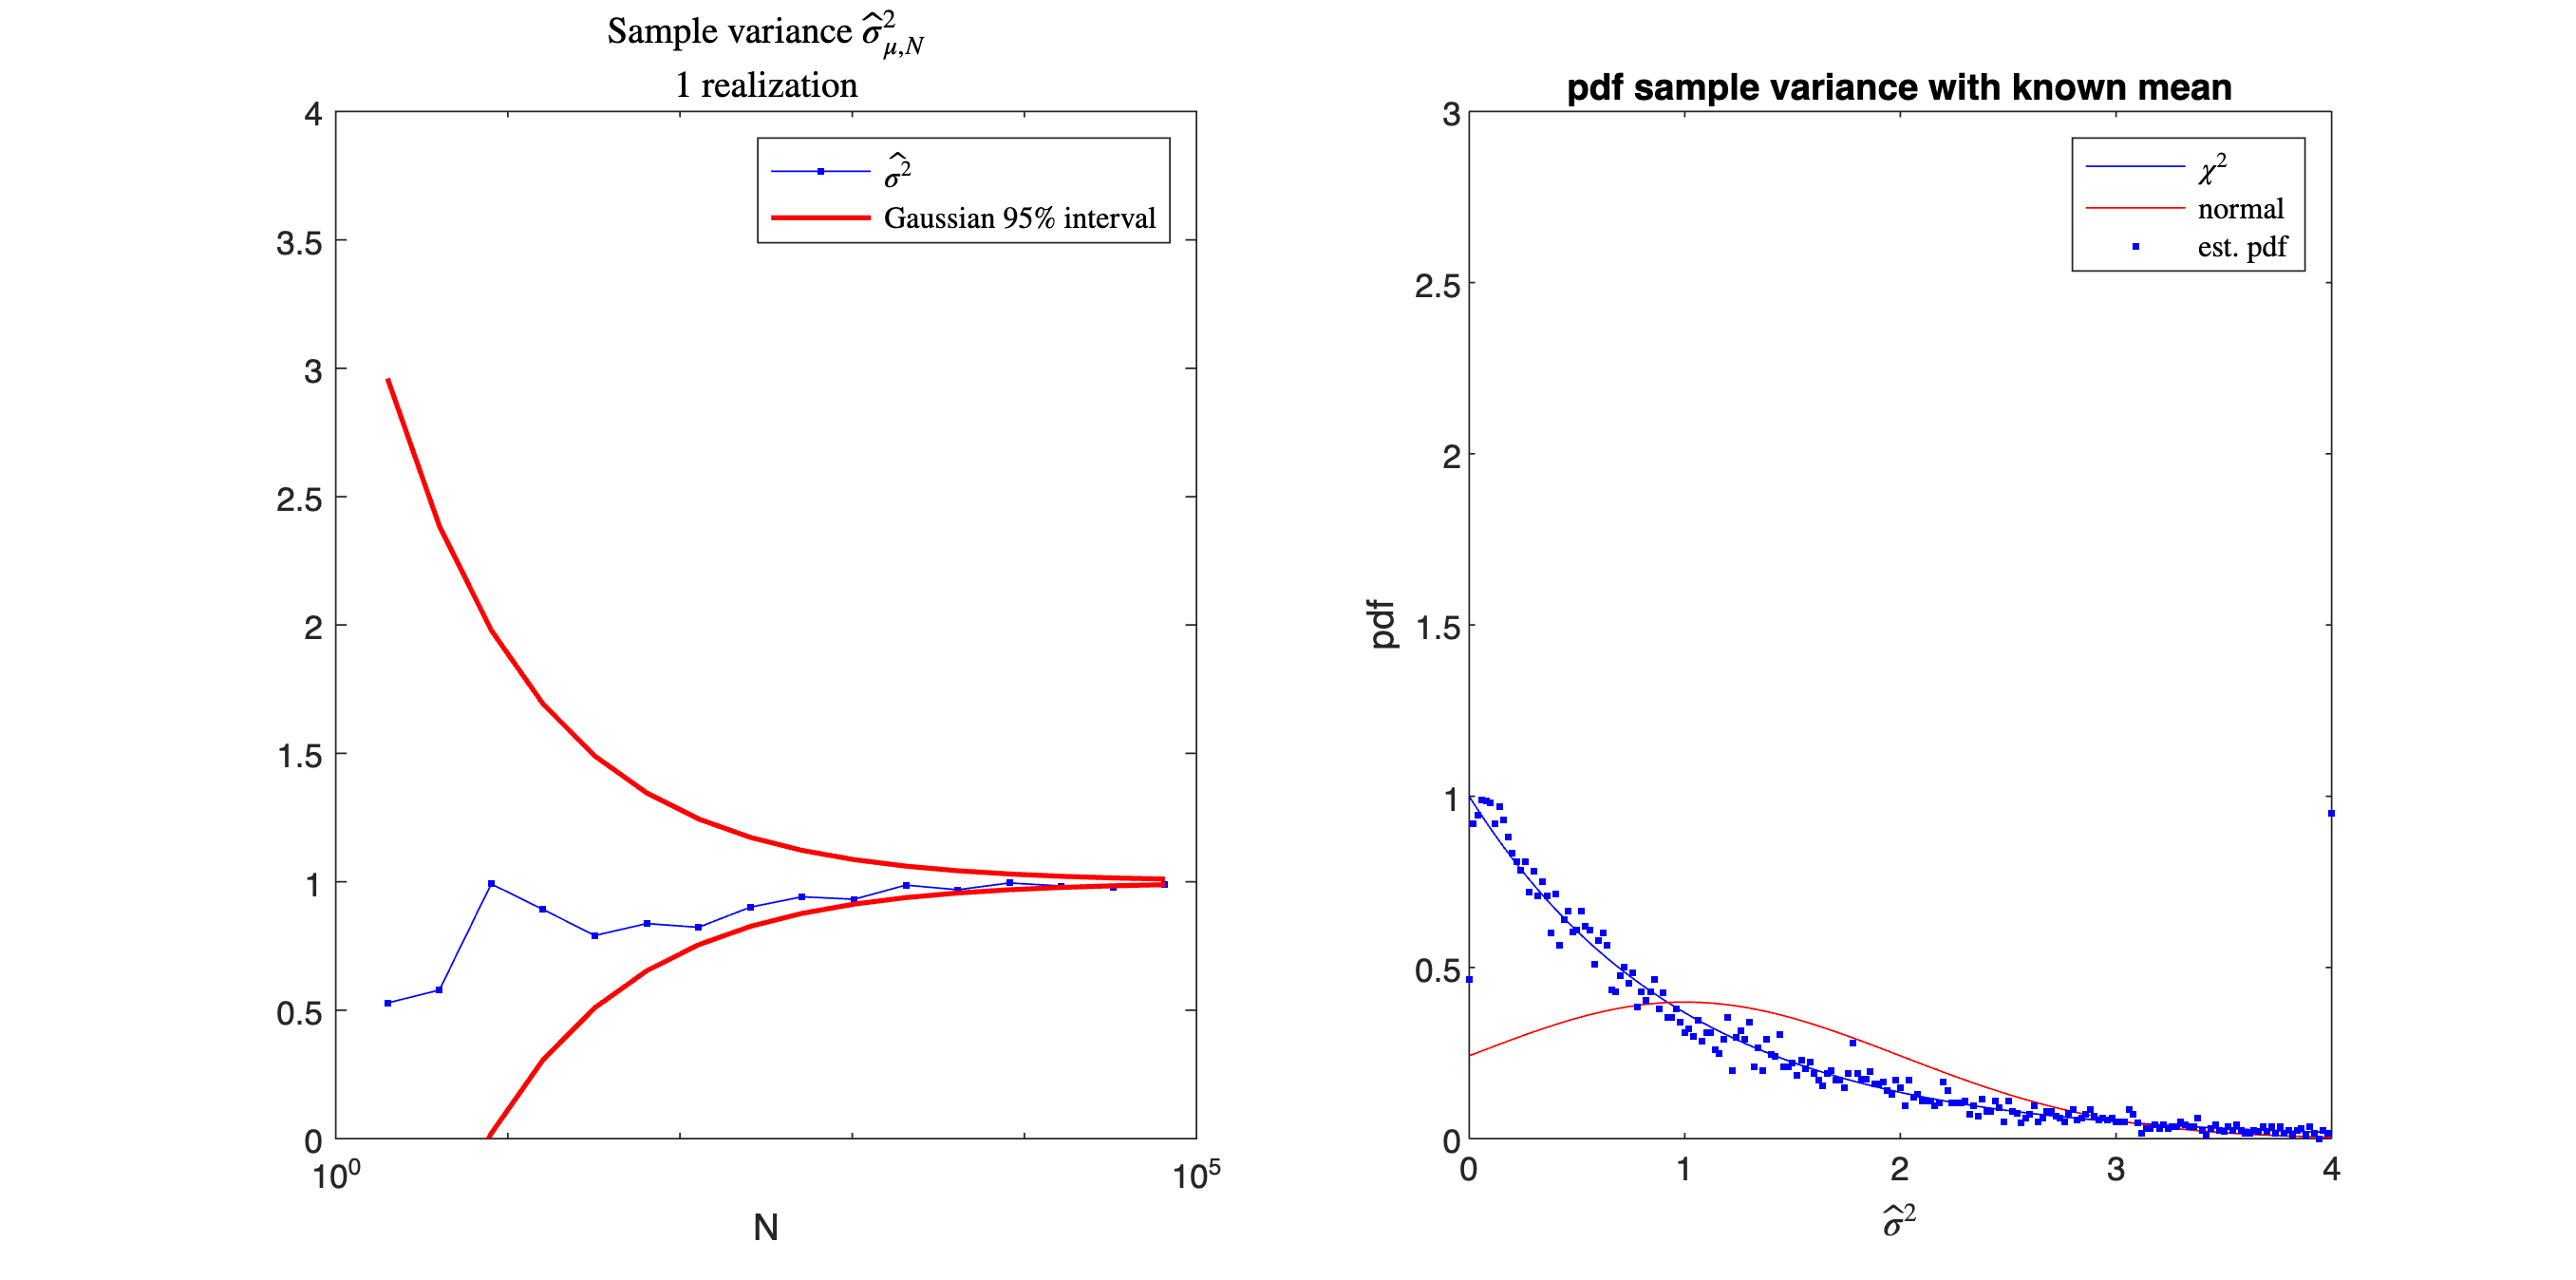


% distribution sample variance
N=2;  % length data records
 
R=1e4;                         % number of realizations


X=randn(N,R);         % generatate data
XvarAll = zeros(1,R);   % Initialize vector

XvarAll = MyVarZeroMean(X,1);   % sample variance with known mean mu=0


figure(3)  % plot distribution

% sample distributions of the sample variance
Center=linspace(0,4,201);d=Center(2)-Center(1);  % centers for the histogram

% estimate pdf for data
[n]=hist(XvarAll,Center);pdfEst=n'/R/d;  % estimated pdf
pdfTh=chi2pdf( Center*N ,N)*N;   % theoretical chi2 pdf
pdfN=normpdf(Center,1,sqrt(2/N));         % normal pdf with same mean and variance

plot(Center,pdfTh,'b',Center,pdfN,'r',Center,pdfEst,'.b'),
axis([0,4,0,3])
ylabel('pdf')
xlabel('$\hat\sigma^2$','interpreter','latex')

title('pdf sample variance with known mean')
legend('$\chi^2$','normal','est. pdf','interpreter','latex')

## The Sample Variance $\hat \sigma^2_{N}$ (using the sample mean) as an Estimator of the Variance of a Distribution

Before we continue with the study of the generation of a confidence interval for the sample variance, we will first address the problem that the true mean value $\mu$ of the sampled data is mostly not known. More formally, the sample variance of $N$ observations $\{x_i\}, i=1,\ldots,N$ of the random variable $X$ using the sample mean $\hat \mu=\frac{1}{N} \sum_{i=1}^{N}x_i$ is defined as


$$ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(x_{i}-\hat \mu_N)^2.$$
 

First we will discuss why a scale factor $N-1$ is used in $\hat \sigma^2_{N}$, instead of the scale factor $N$ as it was in $\hat \sigma^2_{\mu,N}$. Next we will update the distribution of the sample variance $\hat \sigma^2_{\mu,N}$ to get the distribution for $\hat \sigma^2_{N}$. The updated distribution will be used to generate confidence intervals for $\hat \sigma^2_{N}$.

### Replacing the True Mean by the Sample Mean: Impact on the Degrees of Freedom. (Hint: Not for One New to Statistics)

We start from $N$ independent observations $\{x_i\}, i=1,\ldots,N$ of the random variable $X$. As we discussed in the discussion on the distribution of $\hat \sigma^2_{\mu,N}$, we had $N$ degrees of freedom in the sum $\sum _{i=1}^{N}(x_{i}-\mu)^2=\sum _{i=1}^{N}w_i^2$. In $\hat \sigma^2_{N}$, this sum is replaced by $\sum _{i=1}^{N}(x_{i}-\hat \mu_N)^2=\sum _{i=1}^{N} \hat w_i^2$. The impact of recplacing $\mu$ by $\hat \mu$ is that a degree of freedom will be lost. 

*Illustration for *$N=2$ *samples*:  For two observations $x_1,x_2$ we have that

$\hat \mu_2=\frac {x_1+x_2}{2}$, $\hat w_1=x_1-\frac{x_1+x_2}{2}=\frac{x_1-x_2}{2}$, and $\hat w_2=-\frac{x_1-x_2}{2}$,

or $\hat w_1=-\hat w_2$. We can clearly see that both random variables  $\hat w_1, \hat w_2$ can be described by a single random variable $e$, with $\hat w_1=e$ and $\hat w_2=-e$ so that only one degree of freedom remains. 

*Illustration for *$N$ *samples*: By calculating the sample mean $\hat \mu$ we used the data a first time to estimate one parameter. As a result the set of $N$ random variables $\{x_i-\hat \mu_N = \hat w_i\}, i=1,\ldots,N$ has only $N-1$ degrees of freedom. Indeed:

$\sum_{i=1}^N\hat w_i = \sum_{i=1}^N (x_i - \hat \mu_N) = \sum_{i=1}^N x_i - N \hat \mu_N=\sum_{i=1}^N x_i - \sum_{i=1}^N x_i=0$,

shows that there exist a linear relation between $\{\hat w_i\}, i=1,\ldots,N$ so that only $N-1$ degrees of freedom remain from the $N$ degrees of freedom of the original set of $N$ independent observations $\{x_i\}, i=1,\ldots,N$. In general, if there exist $l$ independent linear relations between $\{\hat w_i\}, i=1,\ldots,N$, the degrees of freedom will drop to $N-l$.

*Impact on the calculation of the sample variance*: This is also reflected in the expected values of the sums  $\sum _{i=1}^{N}(x_{i}-\mu)^2$ and $\sum _{i=1}^{N}(x_{i}-\hat \mu_N)^2$ that appear in the calculation of the sample variance. Using $E[x_1^2]=E[x_2^2]=\sigma^2$ and $E[x_1x_2]=0$ (independent variables) we get:

- $\hat \sigma^2_{\mu,N}$ using the exact value $\mu=0$: $E[\sum _{i=1}^{2}(x_{i}-\mu)^2]=E[x_1^2+x_2^2]=2\sigma^2$.

- $\hat \sigma^2_{N}$ using the sample mean $\hat \mu$: $E[\sum_{i=1}^2\hat w_i ^2]= E[(\frac{x_1-x_2}{2})^2]+E[(-\frac{x_1-x_2}{2})^2]=E[\frac{x_1^2}{2}]+E[\frac{x_2^2}{2}]-E[x_1x_2]=\sigma^2$.

So we get that the scaling factor to be used to retrieve the sample variance $\hat \sigma^2_{\mu,N}$ in the first case is $N=2$,  and $N-1=1$ for $\hat \sigma^2_{N}$ in the second case. This result can be easily generalized to arbitrary values of $N$, leading to the previous mentioned result:

$ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(x_{i}-\hat \mu_N)^2$ with $E[\hat \sigma^2_{N}]=\sigma^2$.

### Updated Distribution for the Sample Variance $\hat \sigma^2_{N}$ (Hint: Not for One New to Statistics)

The distribution of  the sample variance $\hat \sigma^2_{\mu,N}$ that used the exact mean $\mu$ was $\hat \sigma^2_{\mu,N}\sim\frac{\sigma^2}{N}\chi^2(N)$ with $\nu=N$ degrees of freedom. When the exact mean is replaced by the sample mean $\hat\mu_N$ that is estimated from the same data, we have seen in the previous section that a degree of freedom is lost. Hence the distribution becomes

 $\hat \sigma^2_{N}\sim\frac{\sigma^2}{N-1}\chi^2(N-1)$ with $\nu=N-1$ degrees of freedom.

The $\chi^2(\nu)$-distribution has a mean value $\mu=\nu$ and a variance $\sigma^2=2\nu$. This implies immediately that  for $\nu=N-1$ the mean value $E[\hat \sigma^2_{N}]=\frac{\sigma^2}{N-1}\nu=\sigma^2$ (which is the value that we already retrieved before), and the variance of $\hat \sigma^2_N$ is $\sigma^2_{\hat \sigma^2_N}=(\frac{\sigma^2}{N-1})^22\nu=\frac{2\sigma^4}{N-1}$. 

### Confidence Interval for the Sample Variance (Hint: Not for One New to Statistics)

In this section, an improved confidence interval for the sample variance is obtained using the knowledge that $\hat \sigma^2_N\sim\frac{\sigma^2}{N-1}\chi^2(N-1)$ or $Z=\frac{N-1}{\sigma^2}\hat \sigma^2_N\sim\chi^2(N-1)$ with $\nu = N-1$ degrees of freedom. Define $Z_\alpha$ as the value for which $P(Z\leq Z_\alpha)=\alpha$, then we have that the $1-\alpha$ confidence interval for $Z$ is given by $[Z_{\alpha/2}\leq Z \leq Z_{1-\alpha/2}]$.  The values $Z_{\alpha/2} $ and $Z_{1-\alpha/2}$ are directly obtained from the cumulative $\chi^2$ distribution. By substituting $Z=\frac{N-1}{\sigma^2}\hat \sigma^2_N$ in this expression, an interval around the true value $\sigma^2$ is retrieved:

$P (\hat \sigma^2_N \in  [\frac{Z_{\alpha/2}}{N-1} \sigma^2,\frac{Z_{1-\alpha/2}}{N-1} \sigma^2]) = 1 - \alpha $.

The estimated sample variance $\hat \sigma^2_N$ will be with a probability $1-\alpha$ in this interval. The interval can also be rewritten around $\hat \sigma^2_N$:

$P (\sigma^2 \in  [ \frac{N-1}{Z_{1-\alpha/2}}\hat \sigma^2_N,\frac{N-1}{Z_{\alpha/2}}\hat \sigma^2_N]) = 1 - \alpha $.

Observe that the position and the width of the interval varies with the actual value of the estimate $\hat \sigma^2_N$. For repeated estimates, $100(1-\alpha)\%$ of these intervals will contain the true value $\sigma^2$. Both representations of the confidence intervals are shown below.

#### Confidence Interval for the Sample Variance $\hat \sigma^2_N$ around the True Value $\sigma^2$ (Hint: Not for One New to Statistics)

In the figure below, 100 realizations of the estimated sample variance $\hat \sigma^2_N$ are shown for a varying number of data $N$ and $\sigma^2=1$. The 95% confidence bounds $\hat \sigma^2_N \in  [\frac{Z_{\alpha/2}}{N-1} \sigma^2,\frac{Z_{1-\alpha/2}}{N-1} \sigma^2]$ with $\alpha=0.05$, calculated using the correct $\chi^2$-distribution (red) and the approximate normal distribution (green), are plotted. Observe that 

- The $\chi^2$-bounds give a good match and cover well the asymmetric behavior of $\hat \sigma^2_N$,

- The normal distribution-based bounds work well only for quite large values of $N$. Even for $N=100$ we still can observe large deviations. For $N<9$, the lower bound equals zero.

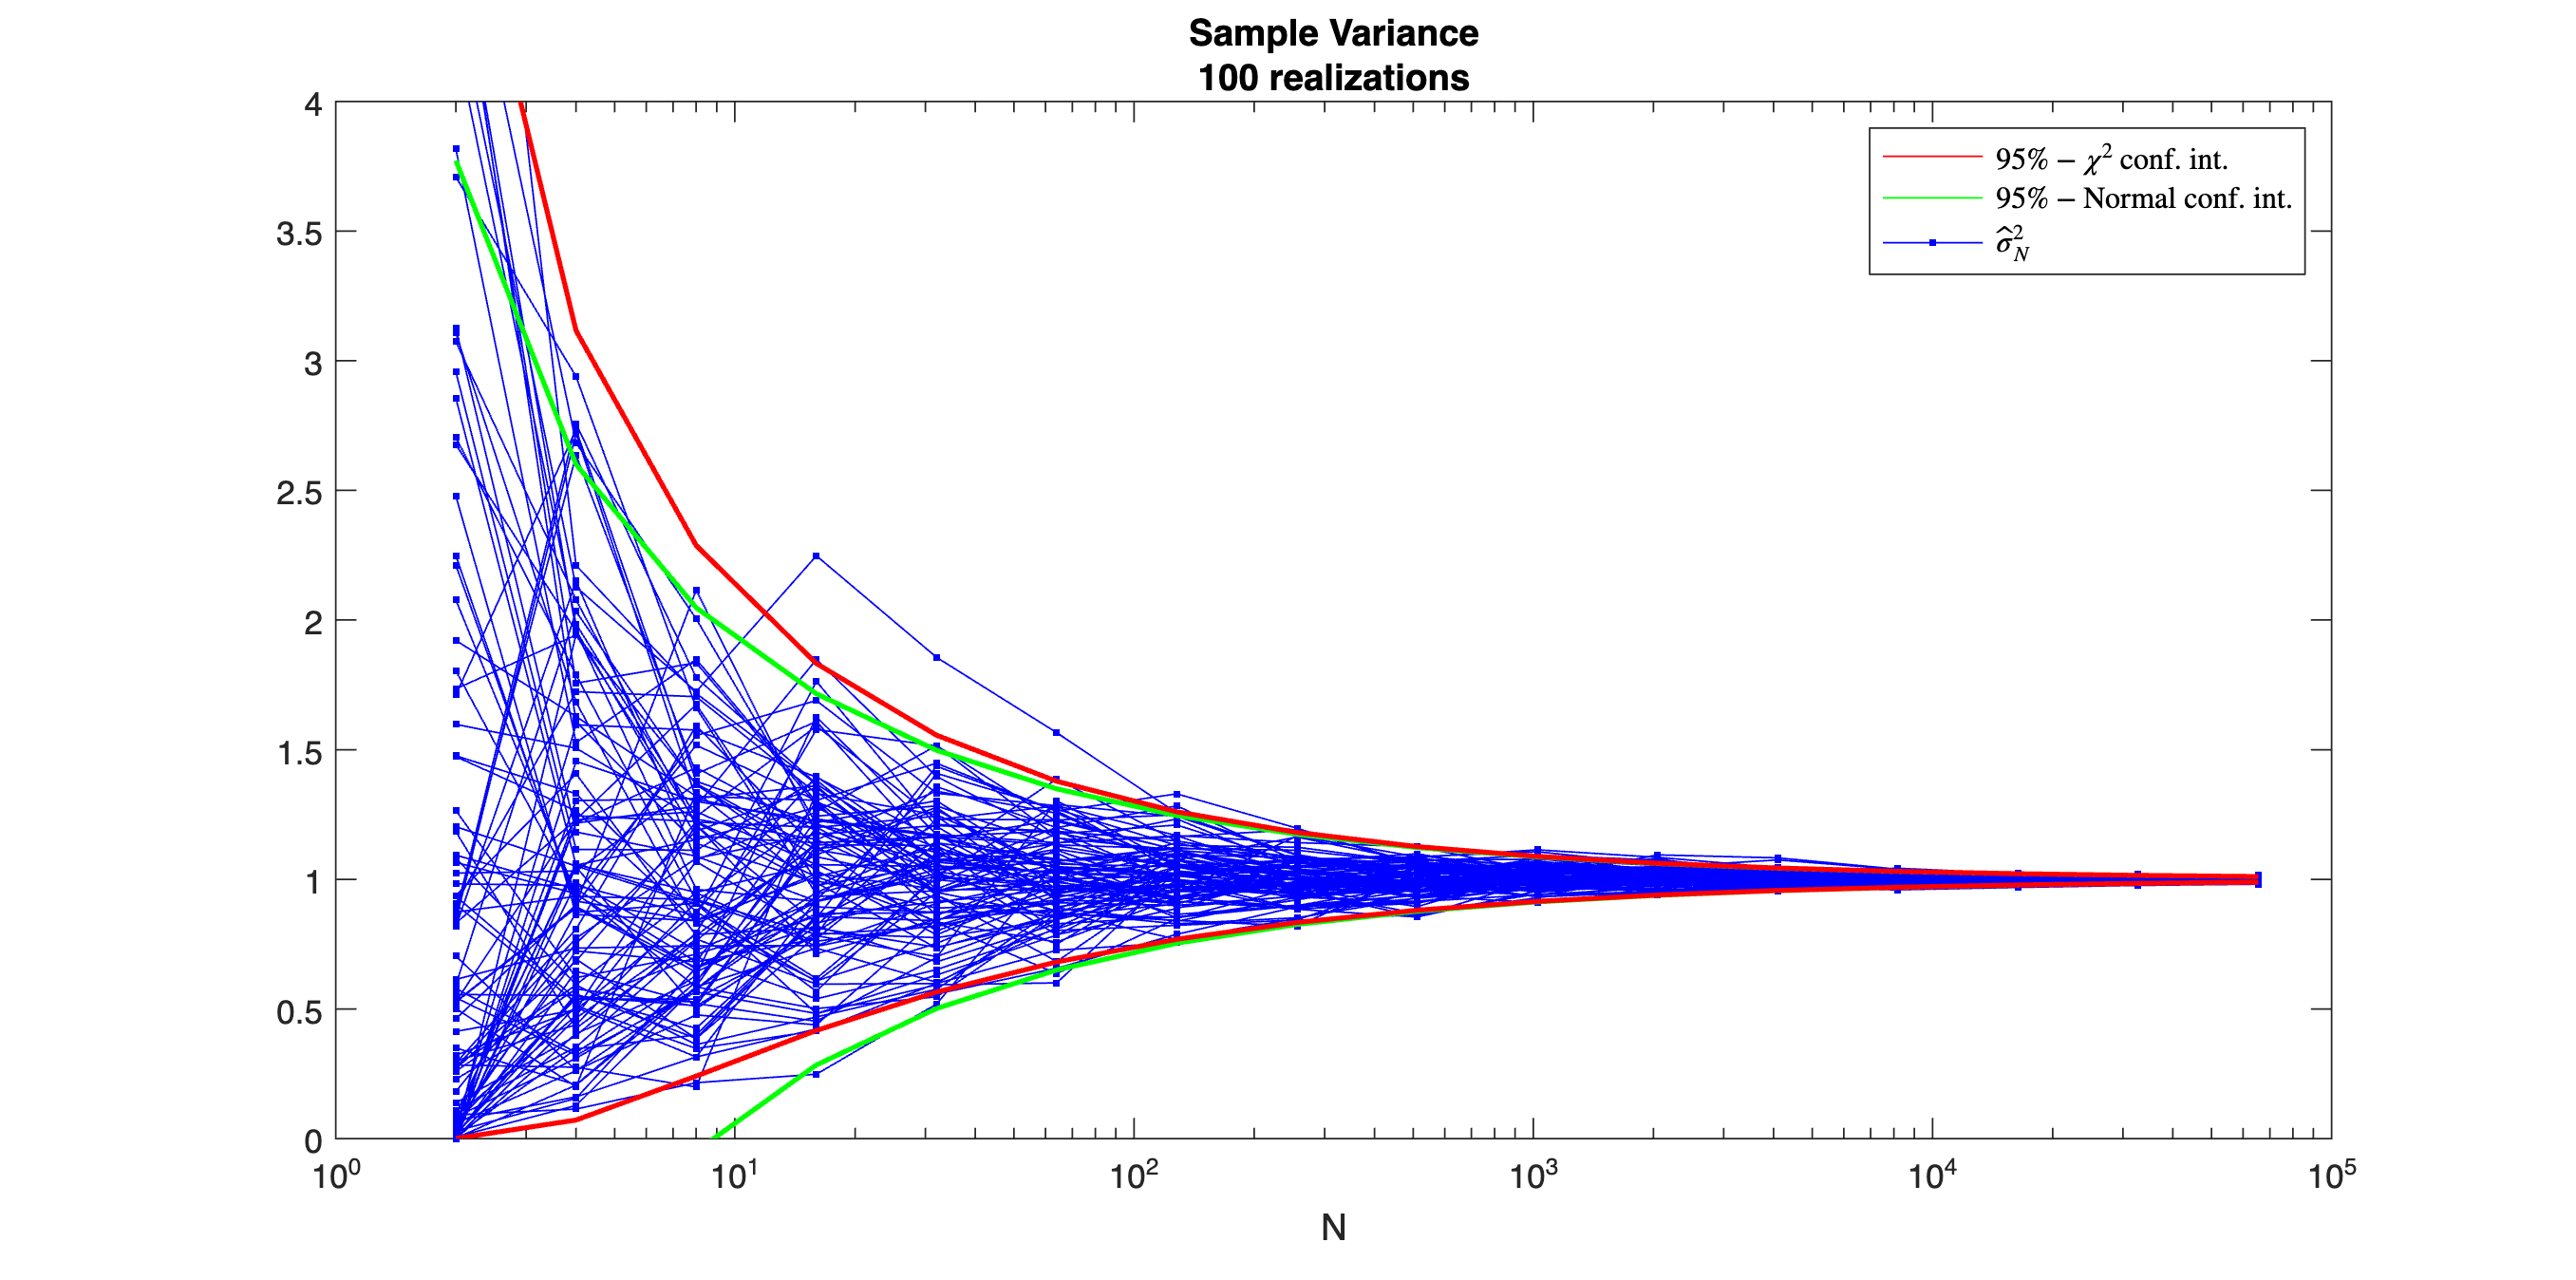


NAll=2.^(1:16);  % lengths of the data records
R=100;           % number of realizations
 
X=randn(max(NAll),R);      % generate the random data
XvarAll=zeros(length(NAll),R);
for k=length(NAll):-1:1    % calculate the variances using sample mean, deviding sum by N-1
XvarAll(k,:)=var(X(1:NAll(k),:),0,1);
end

confLow=chi2inv(0.025,NAll-1)./(NAll-1); %  confidence bounds using chi2 distribution
confHigh=chi2inv(0.975,NAll-1)./(NAll-1); % 

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])

semilogx(NaN,NaN,'r',NaN,NaN,'g',NaN,NaN,'.-b')   % to control the legend

hold on
semilogx(NAll,XvarAll(:,1:R),'.-b')   % plot realizations
hold off

hold on    % plot Gaussian bounds using N-1 degrees of freedom
semilogx(NAll,1+1.96*(2./(NAll-1)).^0.5,'g',NAll,1-1.96*(2./(NAll-1)).^0.5,'g','linewidth',1.5)
hold off
hold on    % plot chi2 bounds
semilogx(NAll,confLow,'r',NAll,confHigh,'r','linewidth',1.5)
hold off

ylim([0 4])
xlabel('N')
title({'Sample Variance','100 realizations'})
legend({'$95\%-\chi^2$ conf. int.','$95\%-$Normal conf. int.','$\hat \sigma^2_N$'},'Interpreter','latex')

#### Confidence Interval for the True Variance $\sigma^2$ around the Sample Variance $\hat \sigma^2_N$ (Hint: Not for One New to Statistics)

In this section, the confidence interval $ [ \frac{N-1}{Z_{1-\frac{\alpha}{2}}}\hat \sigma^2_N,\frac{N-1}{Z_{\frac{\alpha}{2}}}\hat \sigma^2_N]$ for $\sigma^2$ around $\hat \sigma^2_N$ is plotted in the top figure for $R$ realizations of a data set with $N$ independent samples $\{x_i\},i=1,\ldots,N$ drawn from a normal distribution $N(\mu=0,\sigma^2=1)$. The probability $P (\sigma^2 \in  [ \frac{N-1}{Z_{1-\frac{\alpha}{2}}}\hat \sigma^2_N,\frac{N-1}{Z_{\frac{\alpha}{2}}}\hat \sigma^2_N]) = 1 - \alpha $. In the second figure, a simular plot is shown for the confidence interval that is obtained under the normal distribution assumption of the sample variance $\hat \sigma^2_{\mu,N}$.

- The values $N,R$ can be set by the sliders.

- Observe that the position and the width of the confidence interval varies with the actual value of the estimate $\hat \sigma^2_N$. For repeated estimates, $100(1-\alpha)\%$ of these intervals will contain the true value $\sigma^2$. 

- Observe that the difference between both plots grows when $N$ decreases.

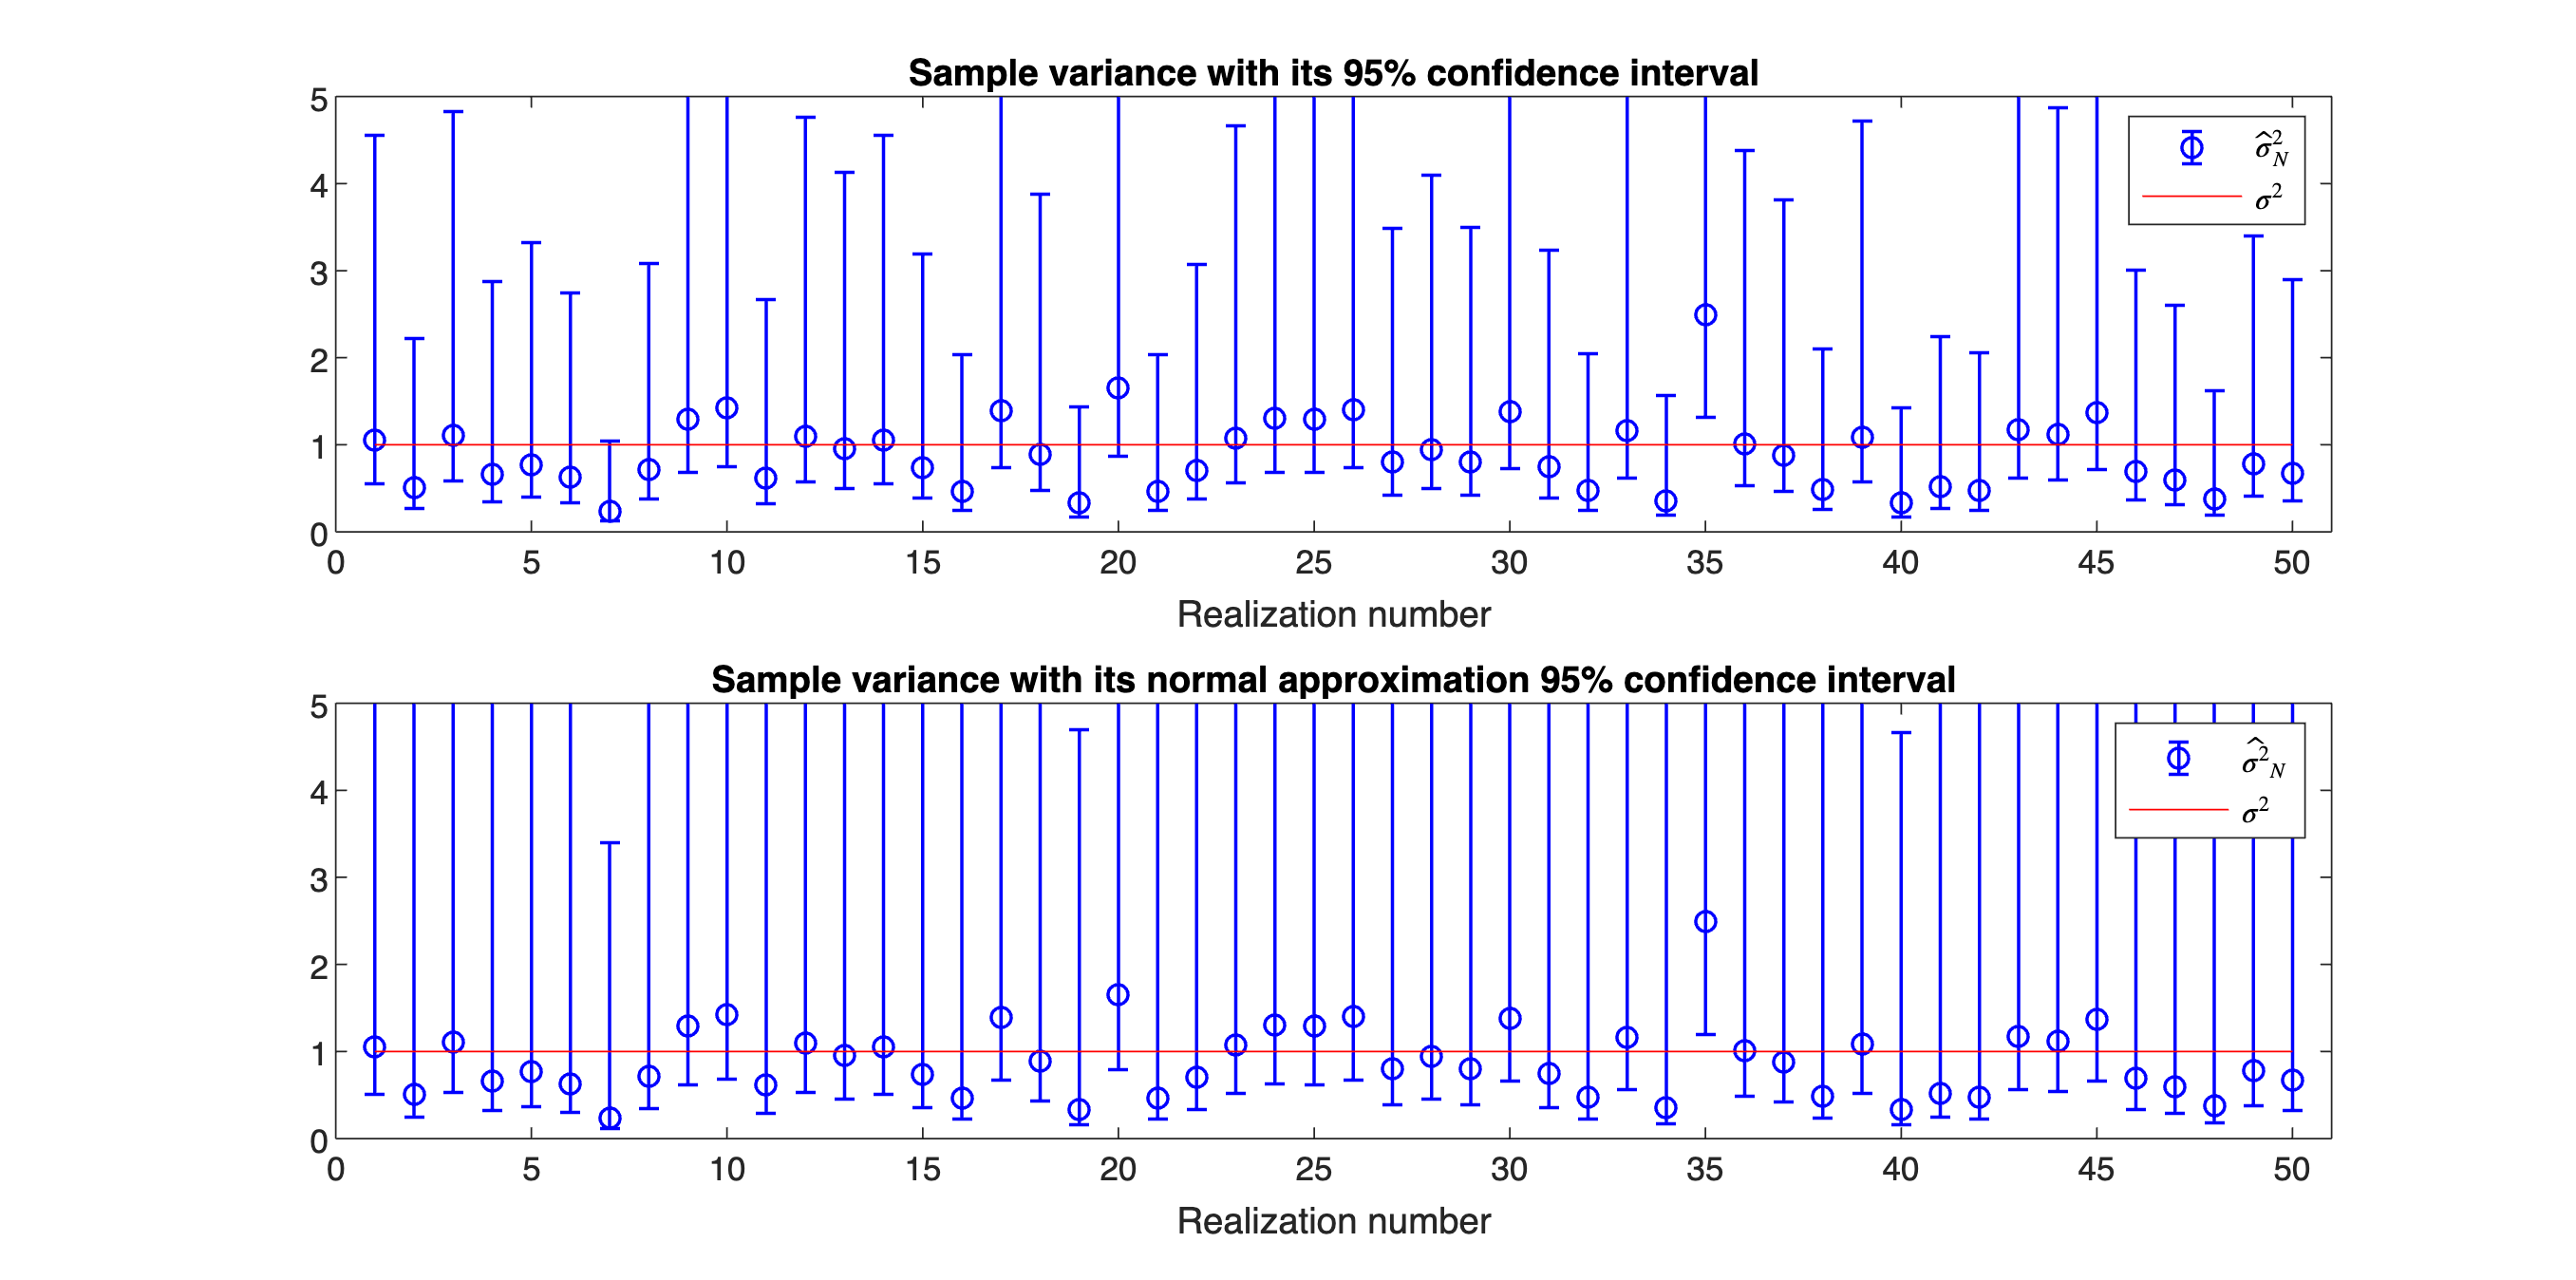


N=10;  % number of samples
R=50;   % number of realizations

 
X=randn(N,R);
XvarAll=var(X,0,1);
confLow=(N-1)./chi2inv(0.975,N-1)*XvarAll; % lower bound
confHigh=(N-1)./chi2inv(0.025,N-1)*XvarAll; % higher bound

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])

subplot(2,1,1)
errorbar([1:R],XvarAll,confLow,confHigh,'ob','linewidth',1)
hold on
plot((1:R),ones(1,R),'r')
hold off
axis([0 R+1 0 5])
legend('$\hat{\sigma}^2_N$','$\sigma^2$','Interpreter','latex')
xlabel('Realization number')
title(['Sample variance with its 95% confidence interval'])

subplot(2,1,2)
a=1.96;   % 95% interval for normal distribution assumption
sigmaVar=sqrt(2)/sqrt(N-1);     % scale factor for the std. dev. the estimated var value
confLow=XvarAll/(1+a*sigmaVar);
confHigh=XvarAll/max(0,(1-a*sigmaVar));  % max operation to avoid a negative value for N<9
errorbar([1:R],XvarAll,confLow,confHigh,'ob','linewidth',1)
hold on
plot((1:R),ones(1,R),'r')
hold off
axis([0 R+1 0 5])
legend('$\hat{\sigma^2}_N$','$\sigma^2$','Interpreter','latex')
xlabel('Realization number')
title(['Sample variance with its normal approximation 95% confidence interval'])

#### Check the quality of the confidence bounds (Hint: Not for One New to Statistics)

From the previous figures, it is not so easy to verify the quality of the bounds generated by the $\chi^2$ distribution and the approximated bounds generated from the normal distribution approximation. In the following illustration, the probabilities $P_{upper,\chi^2}$ and $P_{upper,Norm}$ that the true value $\sigma^2$ is larger than the upper bound of the 95% confidence interval is plotted for different data lengths $N$. For example, $P_{upper,\chi^2}(N)=P(\sigma^2>\frac{N-1}{Z_{\alpha/2}}\hat \sigma^2_N)$ with $\frac{N-1}{Z_{\alpha/2}}\hat \sigma^2_N$ the upper bound of the $\chi^2$-based confidence interval. The probabilities $P_{lower,\chi^2}$ and $P_{lower,Norm}$ that the true value $\sigma^2$ is smaller than the lower bound of the 95% confidence interval are also plotted. The probabilies are estimated from $R=10^5$ realizations of the variance estimate. For the 95% confidence interval ($\alpha=5\%$), these probabilities should be 2.5%.

Observe that the $\chi^2$-based confidence interval provides reliable upper and lower bounds (each with a probability of 2.5% of being exceeded). The approximate bounds generated from the normal distribution approximation are poor for low values of $N$(the upper bound fails completely, it is far too large), but even for $N=1024$ we still can see significante deviations.

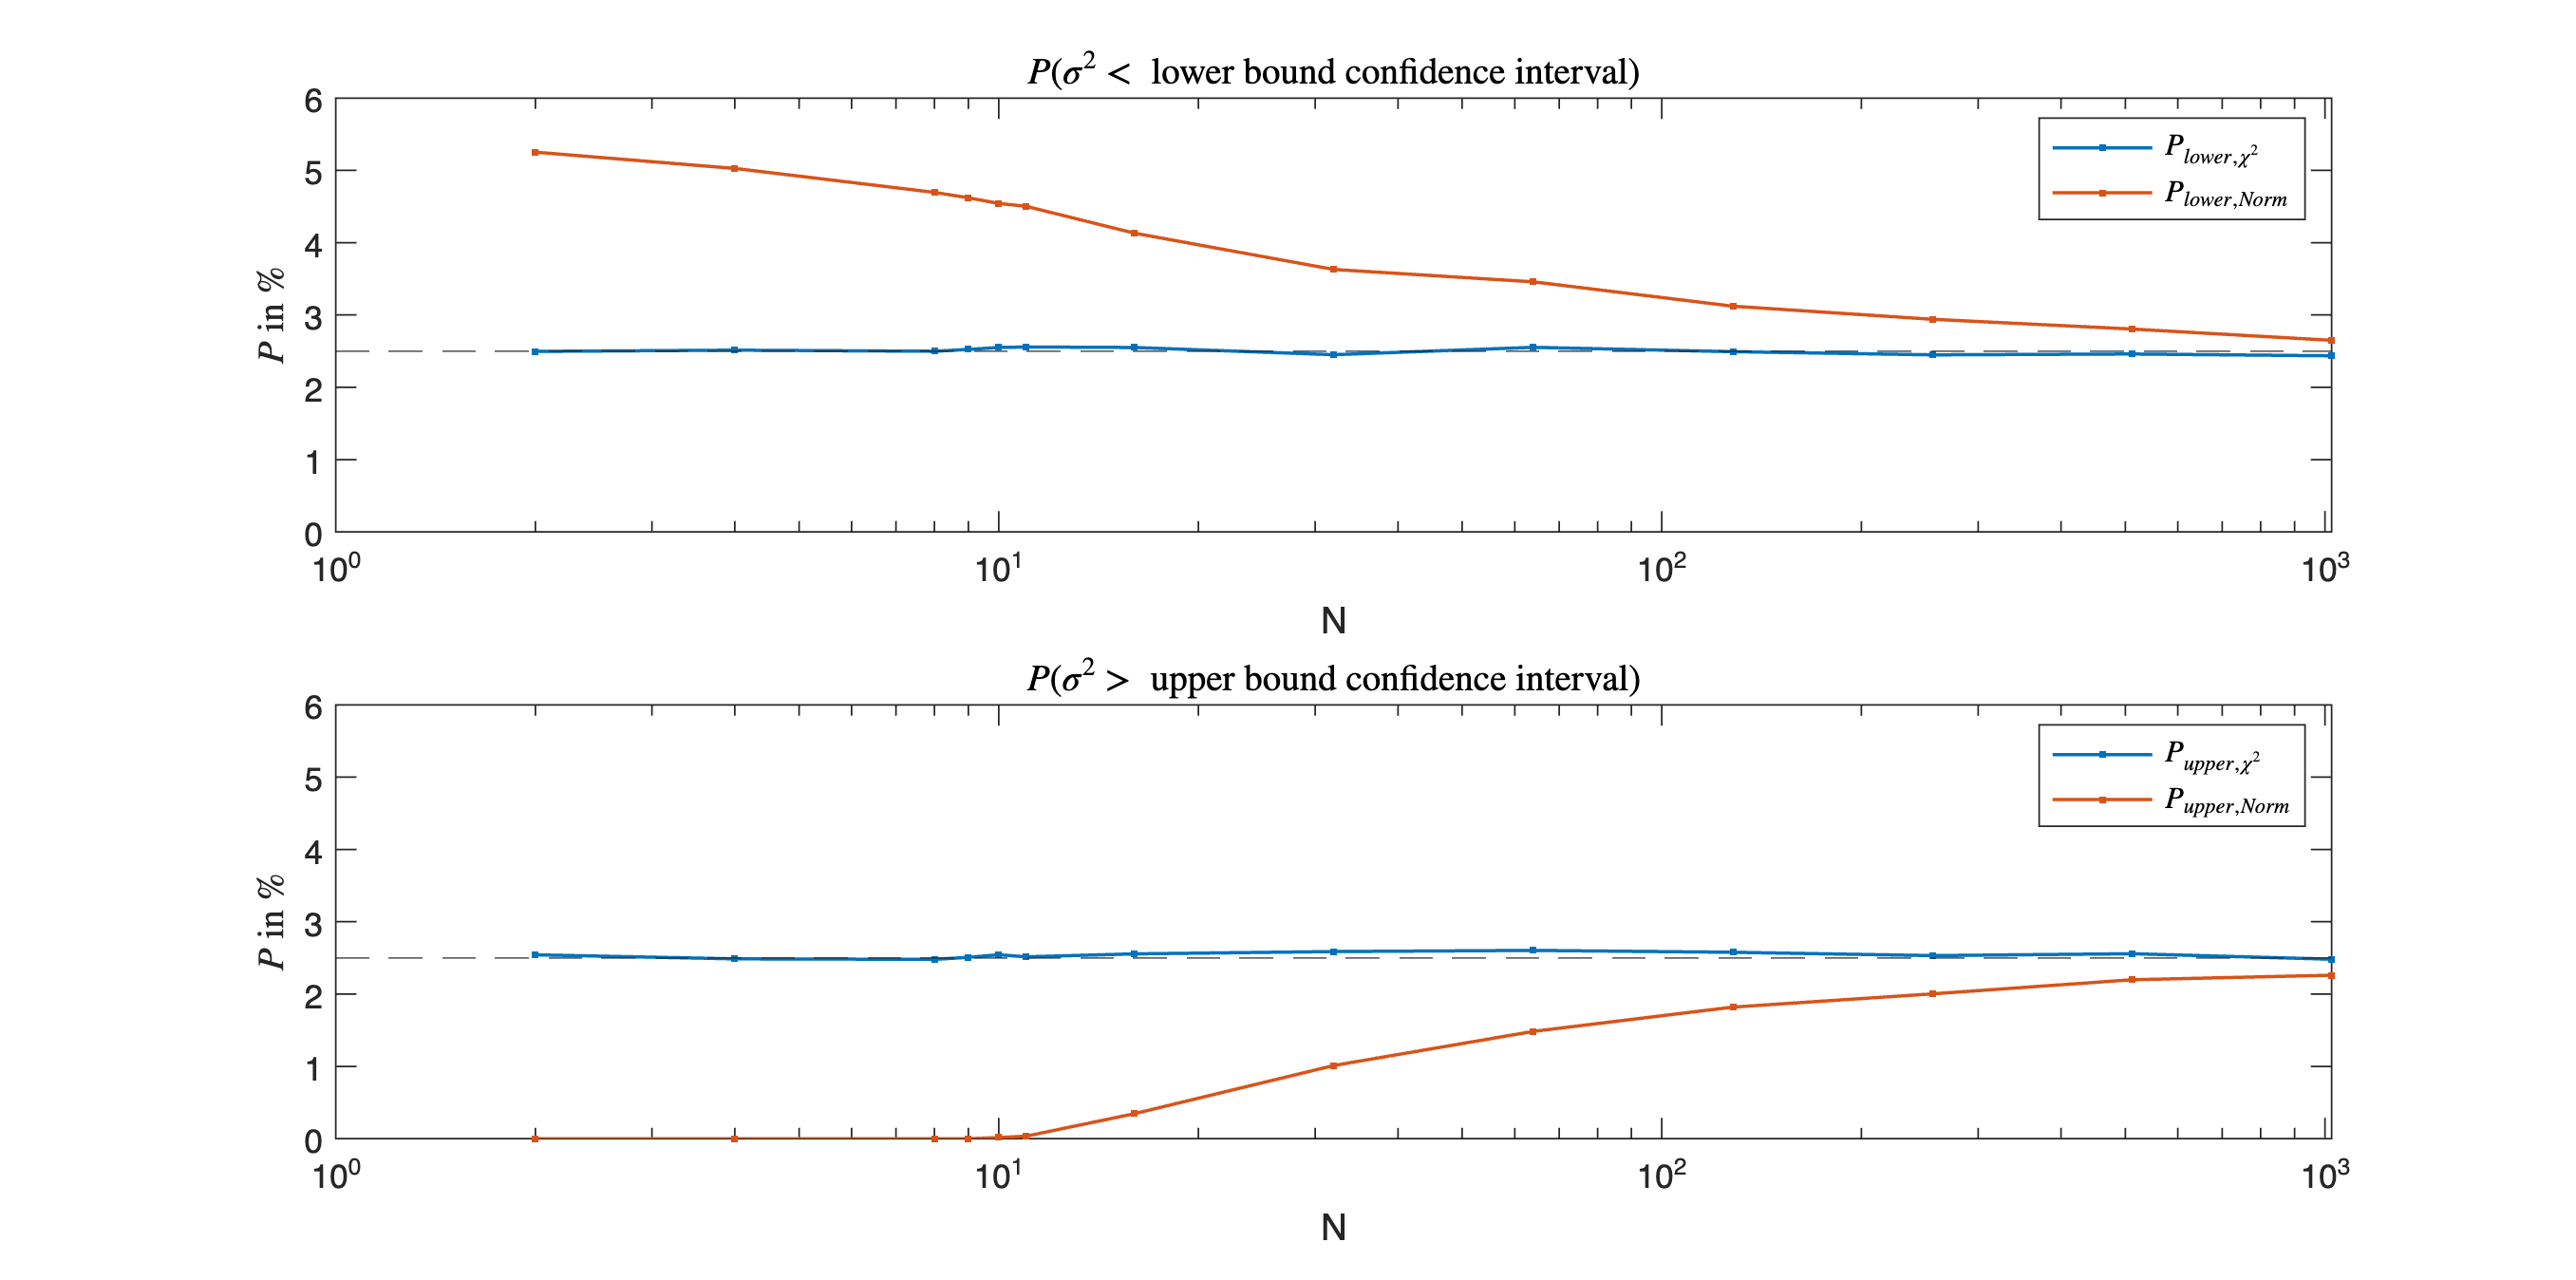

 
Nall=[2 4 8 9 10 11 16 32 64 128 256 512 1024];   % number of samples in the test
R=1e5;   % number of realizations
a=1.96;   % interval [-a sigma, + a sigma] for normal distribution assumption

X=randn(max(Nall),R);   % generate the data

for k=length(Nall):-1:1    % loop over the data lenghts to be tested
  N=Nall(k);
  sigmaVar=sqrt(2)/sqrt(N-1);     % the std. dev. the estimated variance value
  XvarAll=var(X(1:N,:),0,1); % estimate the variance

  confLow=(N-1)./chi2inv(0.975,N-1)*XvarAll; % lower bound
  confHigh=(N-1)./chi2inv(0.025,N-1)*XvarAll; % upper bound

  Test1min=sum(1<confLow);PTestChi2Min(k)=Test1min/R;
  Test1max=sum(1>confHigh);PTestChi2Max(k)=Test1max/R;

  Test2min=sum(1<XvarAll/(1+a*sigmaVar));PTestNormMin(k)=Test2min/R;
  Test2max=sum(1>XvarAll/max(0,(1-a*sigmaVar)));PTestNormMax(k)=Test2max/R;
                  % max operator to avoid negative upperbound for N<9


end

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])

subplot(2,1,1)  % plot lower bound
semilogx(Nall,100*PTestChi2Min,'.-',Nall,100*PTestNormMin,'.-','linewidth',1)
yline(2.5,'--');
ylim([0 6])
legend('$P_{lower,\chi^2}$','$P_{lower,Norm}$','interpreter','latex')
xlabel('N')
ylabel('$P$ in \%','interpreter','latex')
title('$P(\sigma^2<$ lower bound confidence interval)','interpreter','latex')
subplot(2,1,2)  % plot higher bound
semilogx(Nall,100*PTestChi2Max,'.-',Nall,100*PTestNormMax,'.-','linewidth',1)
yline(2.5,'--');
ylim([0 6])
legend('$P_{upper,\chi^2}$','$P_{upper,Norm}$','interpreter','latex')
xlabel('N')
ylabel('$P$ in \%','interpreter','latex')
title('$P(\sigma^2>$ upper bound confidence interval)','interpreter','latex')

## What You Learned

We studied the sample variance as an estimator for the variance of a random variable. 

- The exact mean $\mu$ in  $ \hat \sigma^2_{\mu,N}={\frac {1}{N}}\sum _{i=1}^{N}(x_{i}-\mu)^2$ is replaced by the sample mean in $ \hat \sigma^2_N={\frac {1}{N-1}}\sum _{i=1}^{N}(x_{i}-\hat \mu_N)^2$, which reduces the *degrees-of-freedom* from $N$ to $N-1$. 

- The sample variance $ \hat \sigma^2_N$ has a scaled$\chi^2(N-1)$ distribution with $\nu=N-1$ degrees of freedom.  

- $ \hat \sigma^2_{\mu,N}$ has a scaled $\chi^2(N)$ distribution. 

The $\chi^2$ distribution is an asymmetric distribution, resulting also in asymmetric confidence intervals. 

function Xvar=MyVarZeroMean(X,dim)
% calculates the variance, for a zero mean variable
%      the mean is NOT estimated, the theoretical value 0 is used
[N,R]=size(X);
Xvar=sum(X.^2,dim)/N;   % use known mean mu=0
end